# Linear Algebra Lecture Note(07)

## Matrix Applications

### Code Exercise (07_01)

> Covariance Matrix

%% Clear workspace, command window, and close all figures
clc; clear; close all;

% Define the path to the CSV file on the desktop
% The directory is 'Desktop/LA_Exercise'
numericalData = readtable('dataMat.csv');

% Calculate the mean of each column
columnMeans = mean(numericalData{:,:}, 1);

% Display the means
disp('Column Means:');

Column Means:


disp(columnMeans);

    0.0576    0.4634    0.1796    0.7537    0.1537    0.1440    0.4242    0.4939    0.3363    0.4232    0.0641    0.6963    0.3611    0.5582    0.2916    0.4957    0.4711    0.3178    0.4792    0.3757    0.3503    0.3680    0.2911    0.2035    0.3224    0.3863    0.0555    0.3030    0.3158    0.3833    0.3617    0.3635    0.5011    0.3964    0.4406    0.3912    0.4413    0.4612    0.4345    0.4876    0.4943    0.4877    0.6109    0.6207    0.6640    0.5829    0.5014    0.5267    0.0363    0.2500    0.0301    0.3202    0.3606    0.3991    0.4279    0.1814    0.1821    0.1848    0.1829    0.7859    0.1506    0.2676    0.2519    0.4621    0.4944    0.4041    0.5626    0.1863    0.4952    0.3147    0.0768    0.7195    0.5487    0.2045    0.4333    0.4942    0.2645    0.2431    0.2647    0.2635    0.2689    0.3464    0.3725    0.4230    0.3841    0.4901    0.4498    0.4038    0.0294    0.0228    0.2156    0.6089    0.5351    0.6264    0.6515    0.0652    0.2329    0.1617    0.0941    0.2380

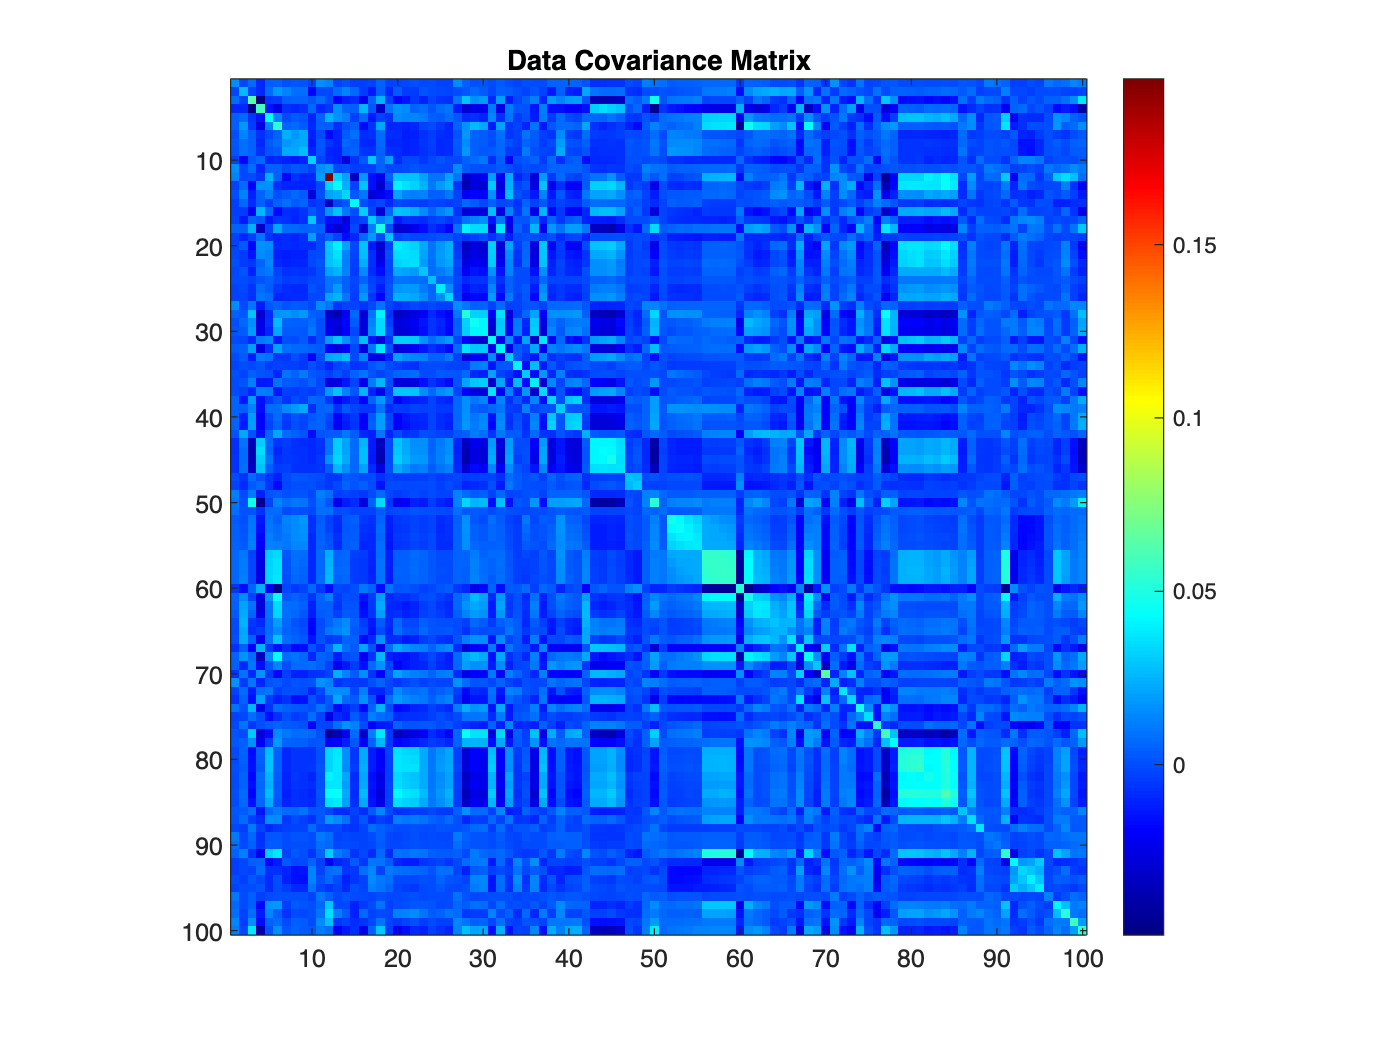


% Mean-center the data
dataMat = numericalData{:,:} - repmat(columnMeans, size(numericalData, 1), 1);

%%%%%%% TODO %%%%%%%
% Compute the covariance matrix using 'cov(matrix)' function
% Refer to the lecture slide 9
covarianceMatrix = cov(dataMat);
%%%%%%%%%%%%%%%%%%%%

% Visualize the covariance matrix
figure;
imagesc(covarianceMatrix);
colorbar;
title('Data Covariance Matrix');
colormap jet; % Use a colorful colormap
axis equal;
axis tight;

%%

### Code Exercise (07_02)

> Correlation from Covariance

%% Clear workspace, command window, and close all figures
clc; clear; close all;

% Define the path to the CSV file on the desktop
% The directory is 'Desktop/LA_Exercise'
numericalData = readtable('dataMat.csv');

% Calculate the mean of each column
columnMeans = mean(numericalData{:,:}, 1);

% Display the means
disp('Column Means:');

Column Means:


disp(columnMeans);

    0.0576    0.4634    0.1796    0.7537    0.1537    0.1440    0.4242    0.4939    0.3363    0.4232    0.0641    0.6963    0.3611    0.5582    0.2916    0.4957    0.4711    0.3178    0.4792    0.3757    0.3503    0.3680    0.2911    0.2035    0.3224    0.3863    0.0555    0.3030    0.3158    0.3833    0.3617    0.3635    0.5011    0.3964    0.4406    0.3912    0.4413    0.4612    0.4345    0.4876    0.4943    0.4877    0.6109    0.6207    0.6640    0.5829    0.5014    0.5267    0.0363    0.2500    0.0301    0.3202    0.3606    0.3991    0.4279    0.1814    0.1821    0.1848    0.1829    0.7859    0.1506    0.2676    0.2519    0.4621    0.4944    0.4041    0.5626    0.1863    0.4952    0.3147    0.0768    0.7195    0.5487    0.2045    0.4333    0.4942    0.2645    0.2431    0.2647    0.2635    0.2689    0.3464    0.3725    0.4230    0.3841    0.4901    0.4498    0.4038    0.0294    0.0228    0.2156    0.6089    0.5351    0.6264    0.6515    0.0652    0.2329    0.1617    0.0941    0.2380


% Mean-center the data
dataMat = numericalData{:,:} - repmat(columnMeans, size(numericalData, 1), 1);

% Compute the covariance matrix
covarianceMatrix = cov(dataMat);

% Visualize the covariance matrix
figure;
imagesc(covarianceMatrix);
colorbar;
title('Data Covariance Matrix');
colormap jet; % Use a colorful colormap
axis equal;
axis tight;

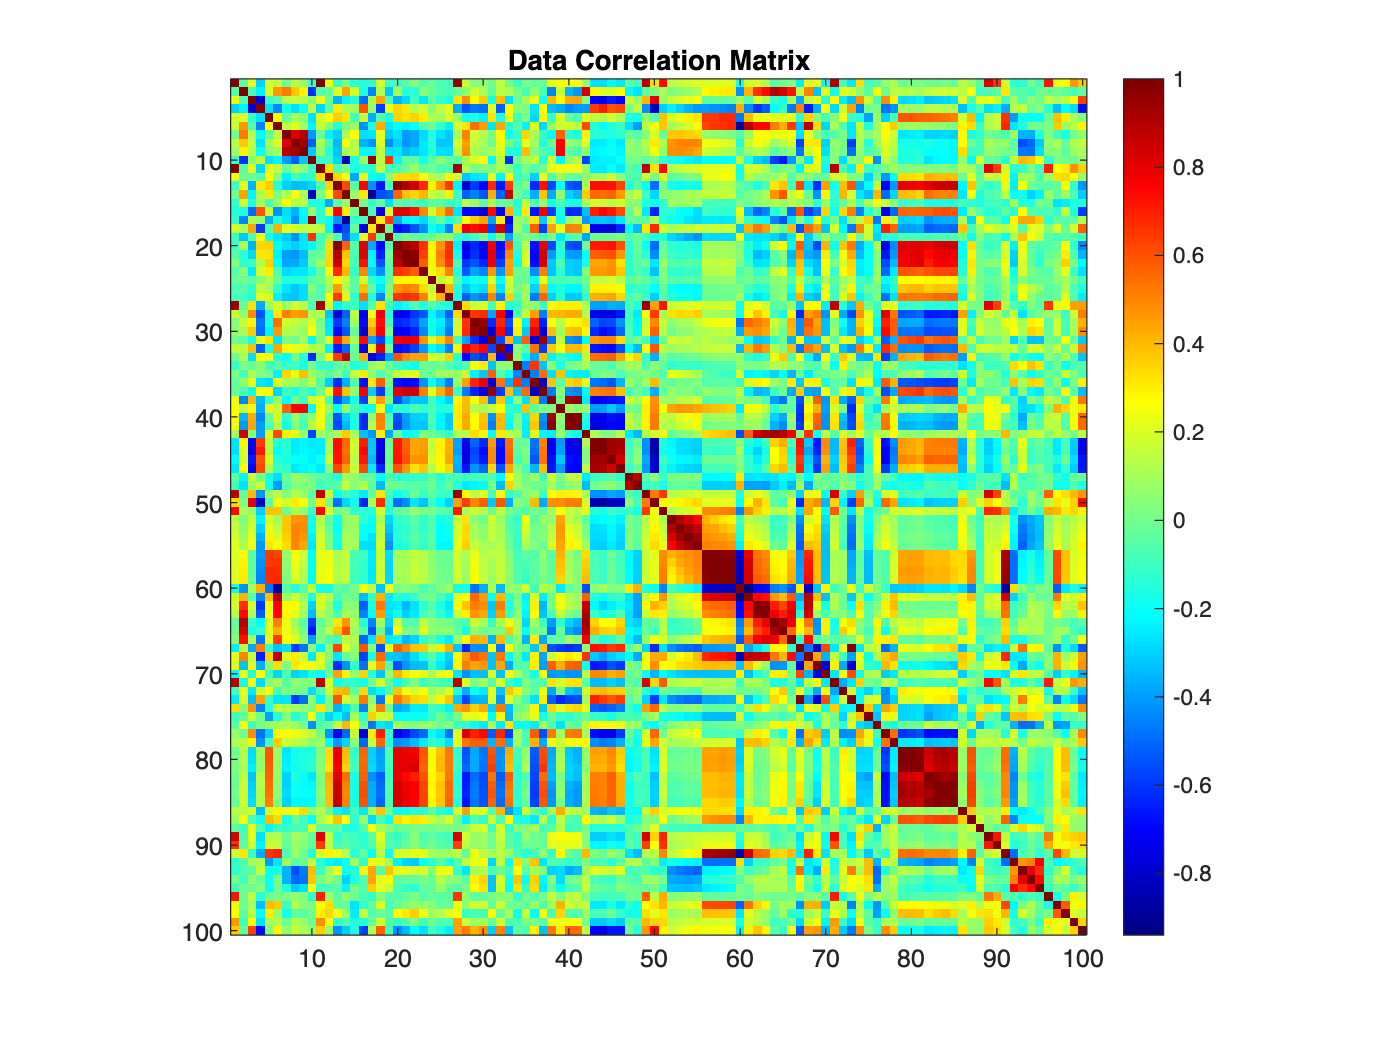


%%%%%%% TODO %%%%%%%
% Compute and visualize the correlation matrix using 'corrcoef(matrix)' function
% Refer to the lecture slide 12
correlationMatrix = corrcoef(dataMat);
%%%%%%%%%%%%%%%%%%%%
figure;
imagesc(correlationMatrix);
colorbar;
title('Data Correlation Matrix');
colormap jet; % Use a colorful colormap
axis equal;
axis tight;

### Code Exercise (07_03)

> Impure Rotation Transformation

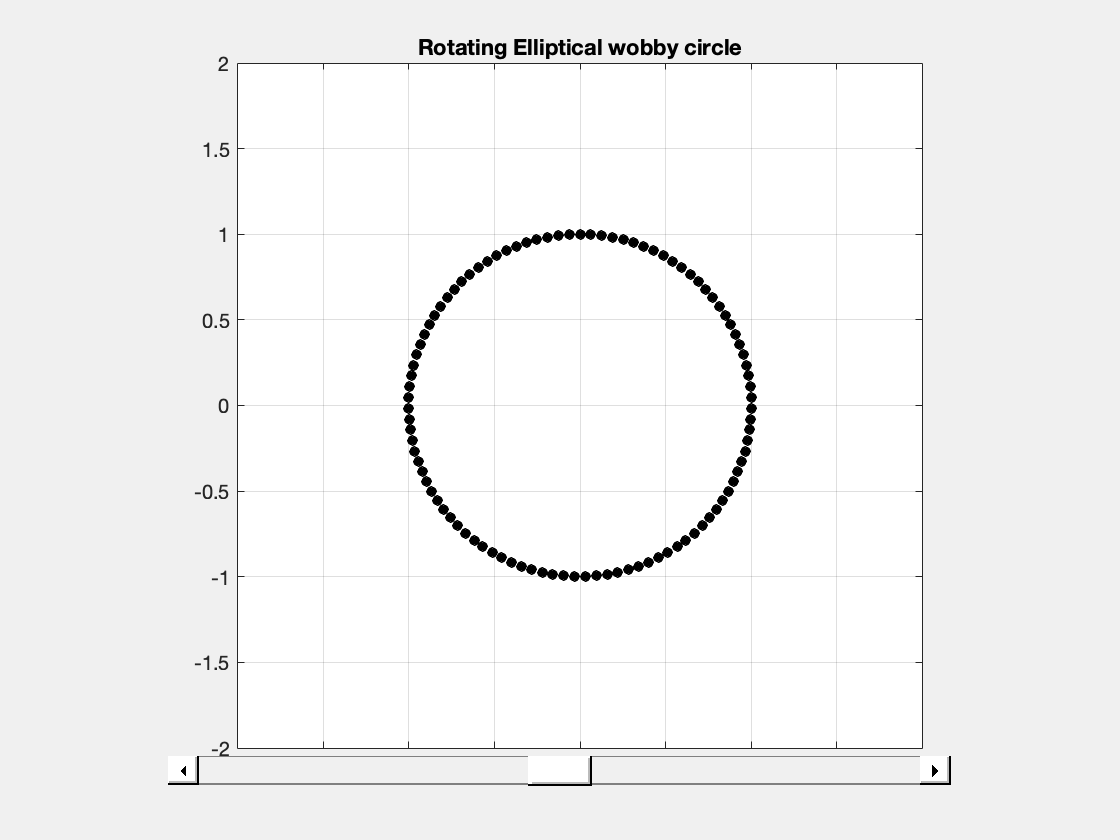

% Clear workspace, command window, and close all figures
clc; clear; close all;

% Define the theta range from 0 to 2*pi with 100 intervals
theta = linspace(0, 2*pi, 100);

% Create an elliptical wobby circle
wobbyCircleX = sin(theta);
wobbyCircleY = cos(theta);

% Prepare the figure
figure;
hPlot = plot(wobbyCircleX, wobbyCircleY, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k');
axis equal;
xlim([-2 2]);
ylim([-2 2]);
grid on;
title('Rotating Elliptical wobby circle');

% Create a slider for controlling the rotation angle
hSlider = uicontrol('Style', 'slider', 'Min', -1, 'Max', 1, 'Value', 0, ...
    'Units', 'normalized', 'Position', [0.15 0.05 0.7 0.05], ...
    'Callback', @(src, event) rotateCircle(src, hPlot, wobbyCircleX, wobbyCircleY));


% Function to rotate the circle
function rotateCircle(src, hPlot, wobbyCircleX, wobbyCircleY)
    % Get the value of the slider
    x = get(src, 'Value');
    
    % Update the title with the current angle
    title(sprintf('Rotating wobby circle - Angle: %.2f', x));
    
    % Define the rotation matrix
    R = [1 1-x*x; 0 1];
    
    %%%%%%% TODO %%%%%%%
    % Create the rotated wobby circle
    % Use '*' function (ex)tranform_matrix * src_mat
    % the src_mat is consist of wobbyCircleX and wobbyCircleY
    % Refer to the lecture slide 22
    rotatedPoints = R * [wobbyCircleX; wobbyCircleY];
    %%%%%%%%%%%%%%%%%%%%
    
    % Update plot data
    set(hPlot, 'XData', rotatedPoints(1,:), 'YData', rotatedPoints(2,:));
end

### Code Exercise (07_04)

> Convolution with predefined kernel.

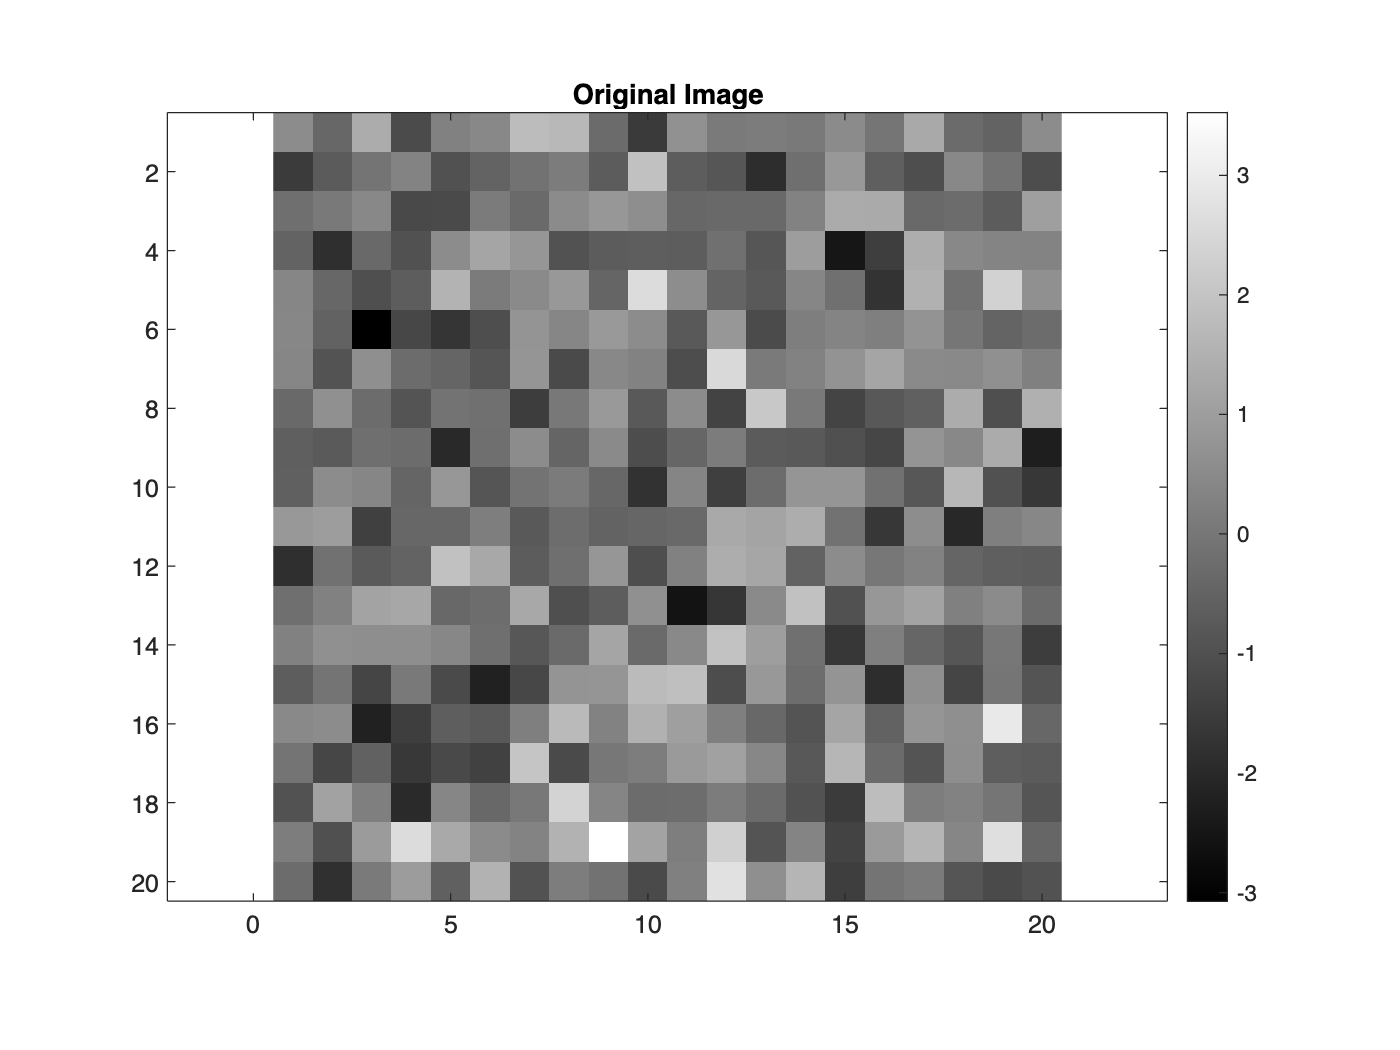

% Clear workspace, command window, and close all figures
clc; clear; close all;

% Initialize image size
imgN = 20;
image = randn(imgN, imgN);

% Initialize convolution kernel
kernelN = 20;
[X, Y] = meshgrid(linspace(-3, 3, kernelN+1), linspace(-3, 3, kernelN+1));
kernel = exp(-(X.^2 + Y.^2) / kernelN);
kernel = kernel / sum(kernel(:)); % Normalize kernel

% Prepare for convolution
halfKr = floor(kernelN / 2);
convoutput = zeros(imgN + kernelN, imgN + kernelN);

% Add padding to the image manually (replacing padarray)
imagePad = zeros(size(convoutput));
imagePad(halfKr + 1:end-halfKr, halfKr + 1:end-halfKr) = image;

% Perform convolution for each pixel of the image
for rowi = halfKr + 1 : imgN + halfKr
    for coli = halfKr + 1 : imgN + halfKr
        % Extract a piece of the image
        pieceOfImg = imagePad(rowi - halfKr : rowi + halfKr, coli - halfKr : coli + halfKr);
        
        %%%%%%% TODO %%%%%%%
        % Dot product: element-wise multiplication and sum
        % Use '.*' function to element-wise multiplication
        % Input is pieceOfImg and kernel
        % Output is the sum of element of element-wise multiplicaited matrix
        % Refer to the lecture slide 32
        dotprod = sum(sum(pieceOfImg .* kernel));
        %%%%%%%%%%%%%%%%%%%%
        
        % Store the result for this pixel
        convoutput(rowi, coli) = dotprod;
    end
end

% Trim the edges
convoutput = convoutput(halfKr + 1:end-halfKr, halfKr + 1:end-halfKr);

% Visualize the original image
figure;
imagesc(image);
axis equal;
colormap gray;
colorbar;
title('Original Image');

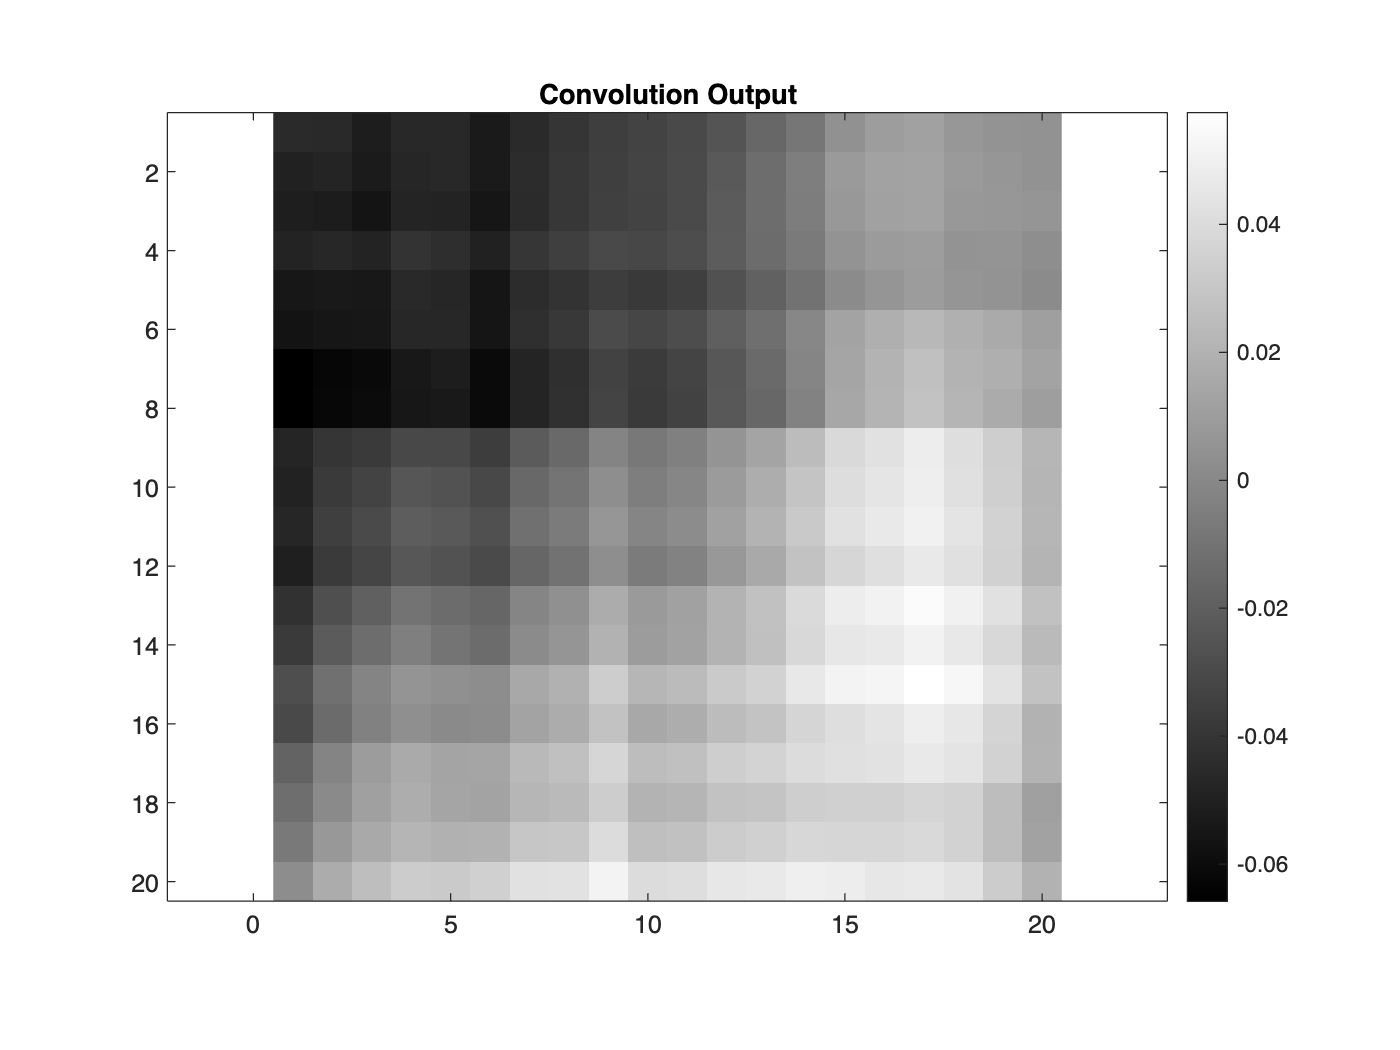


% Visualize the convolution output
figure;
imagesc(convoutput);
axis equal;
colormap gray;
colorbar;
title('Convolution Output');

## Assignment Section

### Exercise 1: Covariance and Correlation Matrices

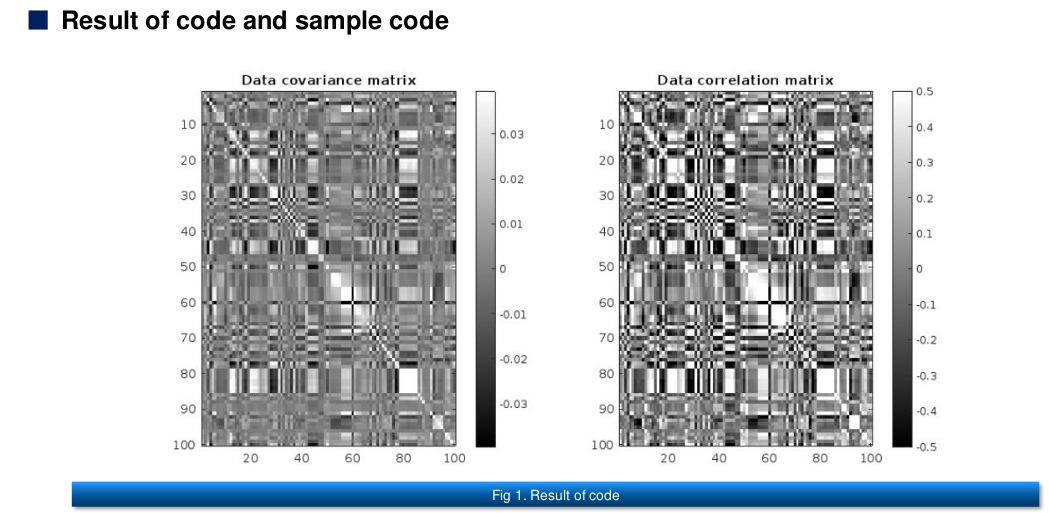

% Clear workspace, command window, and close all figures
clc; clear; close all;

% Define the path to the CSV file
data_path = 'dataMat.csv';

% Read the data from the URL into a table
data = readtable(data_path, 'FileType', 'text', 'Delimiter', ',');
dataMat = table2array(data);

% write here (start)
% Compute the mean of each data feature
datamean = mean(dataMat,1);

% Mean-center the data
dataMatM = dataMat - repmat(datamean, size(dataMat, 1), 1);

% Confirm that any given feature has mean=0 (or very close...)
disp('Mean of the first feature after centering: ');

Mean of the first feature after centering: 


disp(mean(dataMatM(:, 1)))

  -9.9107e-17



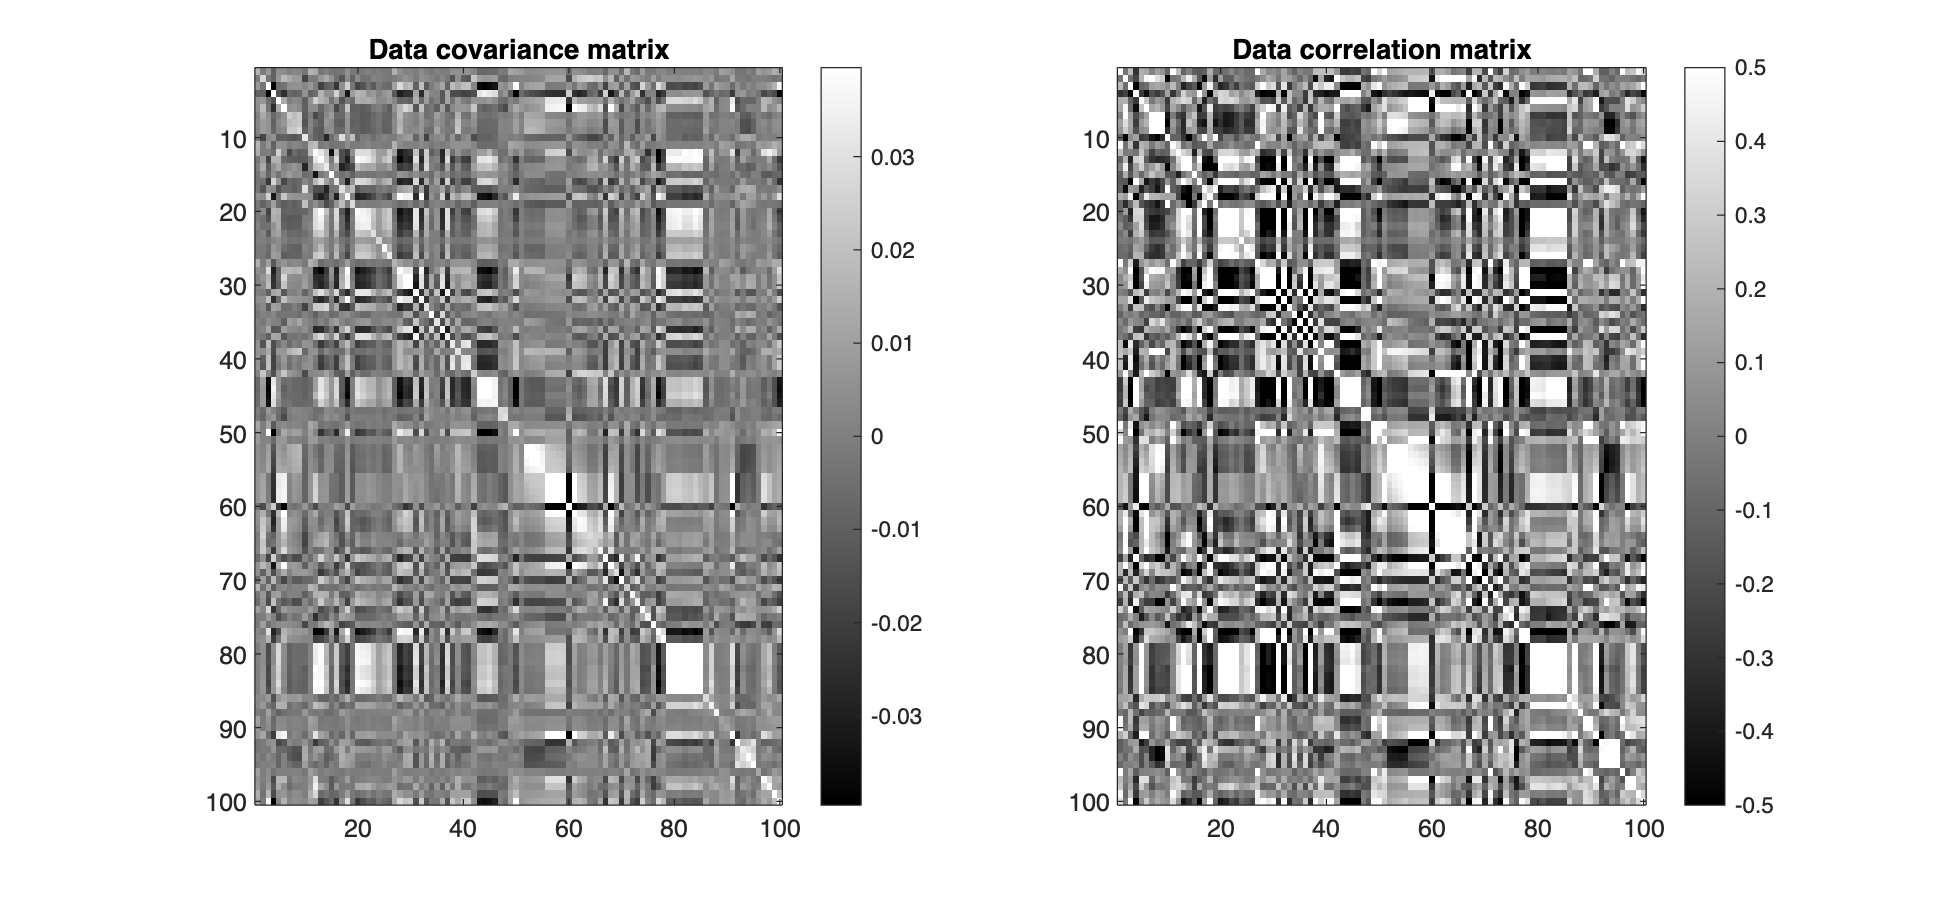


% Compute the covariance matrix
covMat =cov(dataMatM);

% Diagonal matrix of inverse standard deviations
variances = diag(covMat); % Extract diagonal elements (variances) from the covariance matrix
standard_devs = sqrt(variances);
S = diag(1 ./ standard_devs); % Create diagonal matrix of inverse standard deviations

% Compute the correlation matrix
% R = S*C*S
corrMat = S*covMat*S;

% write here (end)

% Dynamic color scaling
% Just for visualization
clim = max(abs(covMat(:))) * 0.2;

% Visualization of the covariance and correlation matrices
figure('Position', [100, 100, 1300, 600]);

% Plot the covariance matrix
subplot(1, 2, 1); % First subplot
imagesc(covMat, [-clim, clim]); % Display the covariance matrix
colormap('gray'); % Use gray colormap
title('Data covariance matrix', 'FontWeight', 'bold');
colorbar; % Show color scale

% Plot the correlation matrix
subplot(1, 2, 2); % Second subplot
imagesc(corrMat, [-0.5, 0.5]); % Display the correlation matrix
colormap('gray'); % Use gray colormap
title('Data correlation matrix', 'FontWeight', 'bold');
colorbar; % Show color scale

### Exercise 2: Geometric Transformations

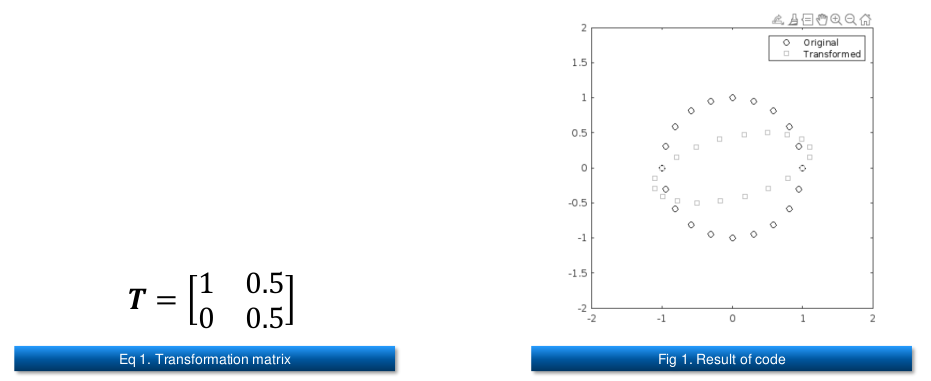

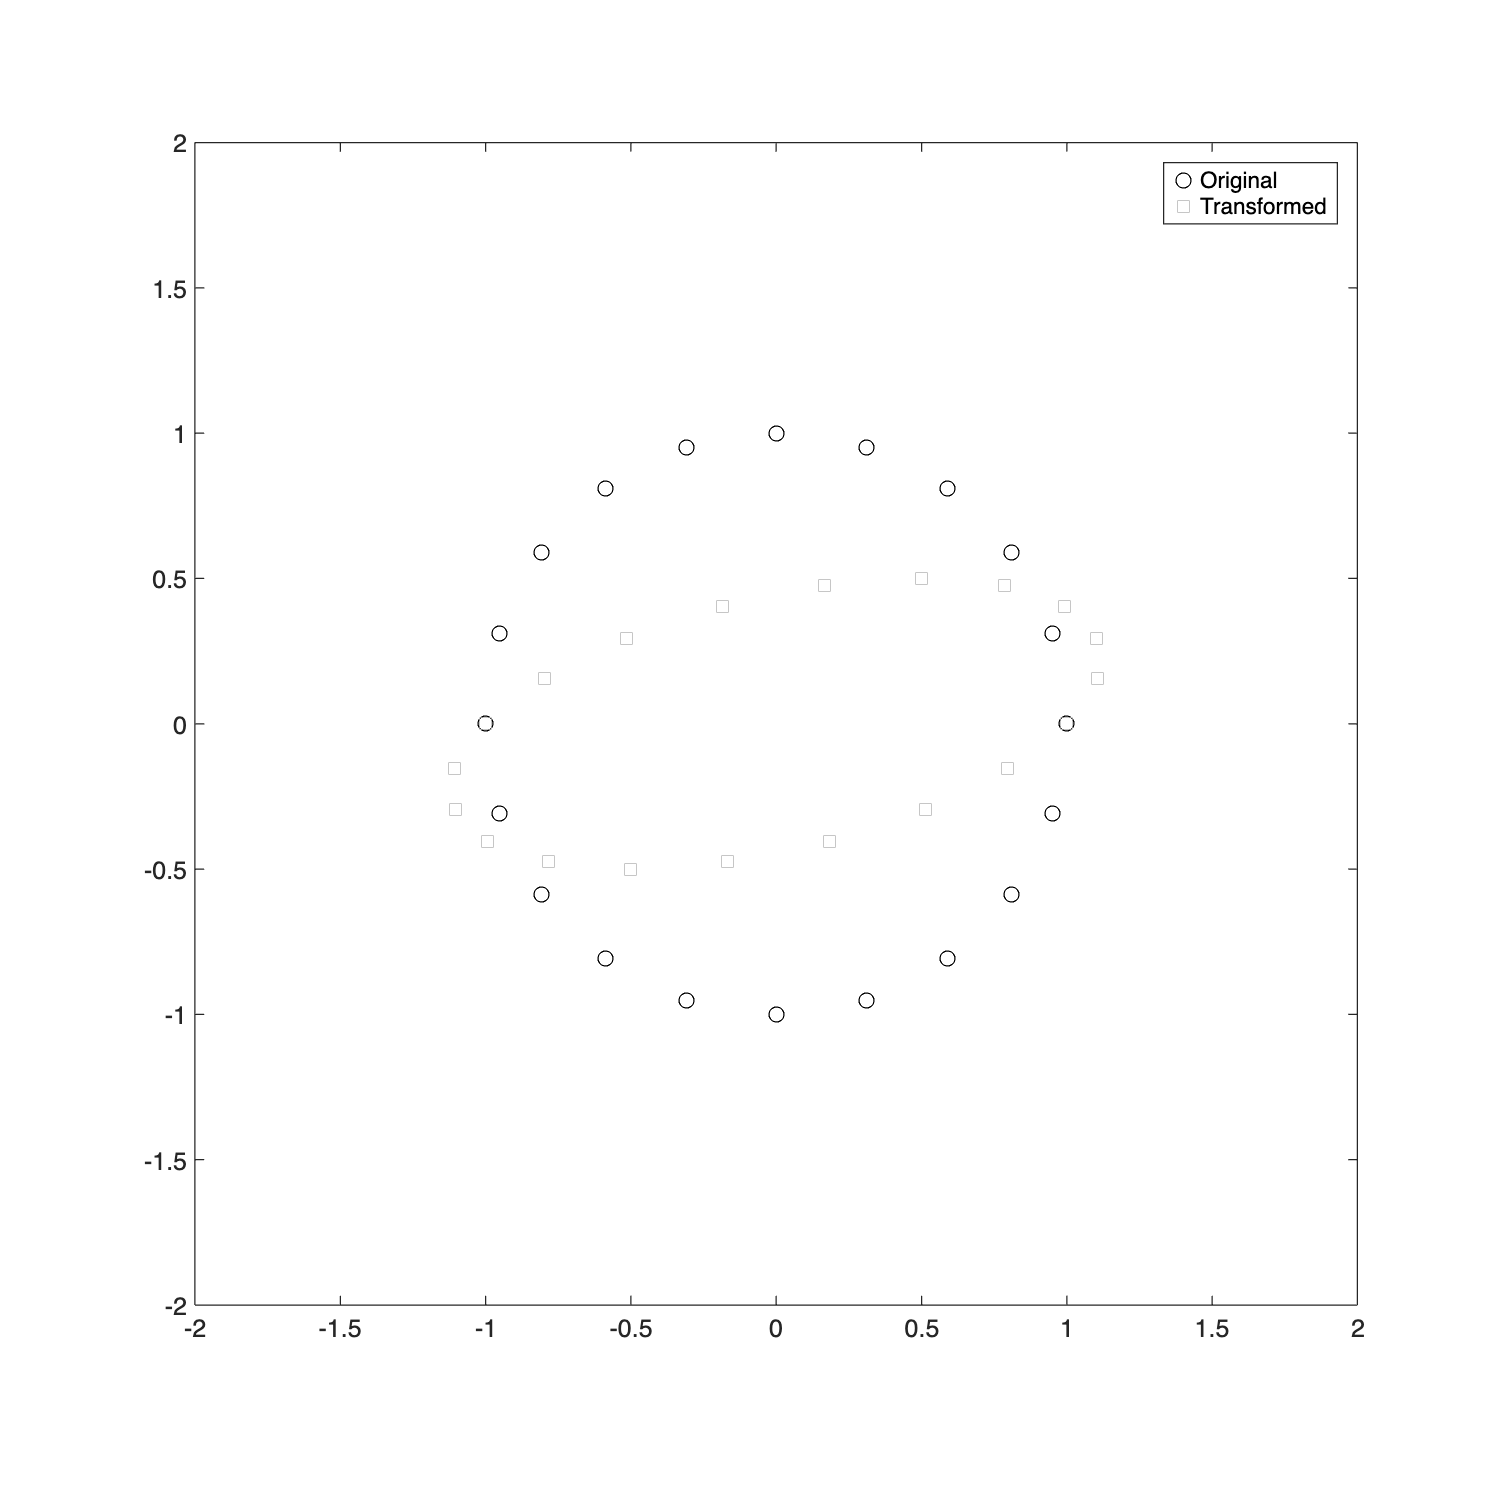

% ■ The goal of this exercise is to show points in a circle before and after applying a
% transformation
% ■ Use Eq 1. and then create a graph that looks like Fig 1..
% Clear workspace, command window, and close all figures
clc; clear; close all;

% Write here (start)
% Transformation matrix
T =[1 0.5; 
    0 0.5];
% Write here (end)

% Define the set of points (a circle)
theta = linspace(0, 2*pi - 2*pi/20, 20);
origPoints = [cos(theta); sin(theta)];

% Write here (start)
% Apply transformation
transformedPoints = T * origPoints;
% Write here (end)

% Plot the points
figure('Position', [100, 100, 600, 600]); % Create a figure window
plot(origPoints(1,:), origPoints(2,:), 'ko'); hold on; % Plot original points
plot(transformedPoints(1,:), transformedPoints(2,:), 's', 'Color', [0.7, 0.7, 0.7]); % Plot transformed points

axis square;
xlim([-2, 2]);
ylim([-2, 2]);
legend('Original', 'Transformed'); % Correctly add legend here

### Exercise 3: Image Feature Detection

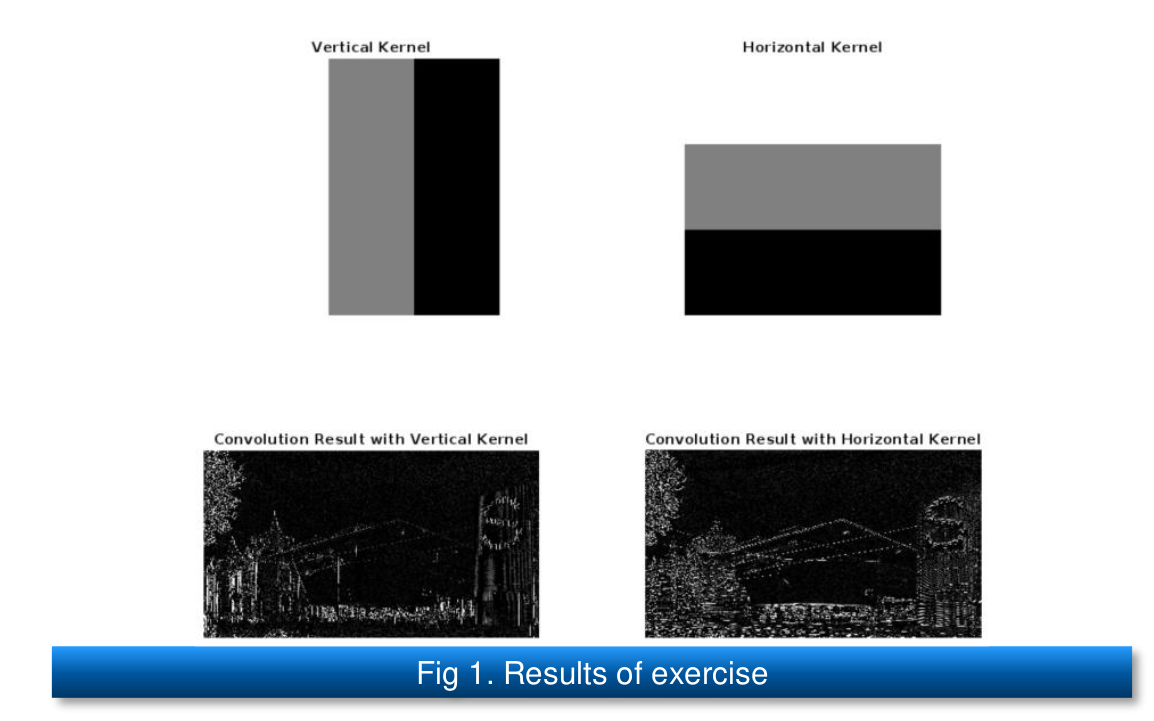

% ■ Technically, image smoothing is feature extraction, because it involves extracting
% the smooth features of the signal while dampening the sharp features. Here we will
% change the filter kernels to solve other image feature detection problems: identifying
% horizontal and vertical lines.
% ■ The two kernels are shown in Fig 1., as are their effects on the image. You can
% handcraft the two kernels based on their visual appearance; they are 𝟑 × 𝟑 and
% comprise only the numbers −𝟏, 𝟎 and +𝟏. Convolve those kernels with the 2D
% grayscale picture to create the feature maps shown in Fig 1..

% Clear workspace, command window, and close all figures
clc; clear; close all;

% Read an image from the web
url = 'https://upload.wikimedia.org/wikipedia/commons/6/61/De_nieuwe_vleugel_van_het_Stedelijk_Museum_Amsterdam.jpg';
bathtub = webread(url);

% Check the size
disp(size(bathtub));

        1675        3000           3



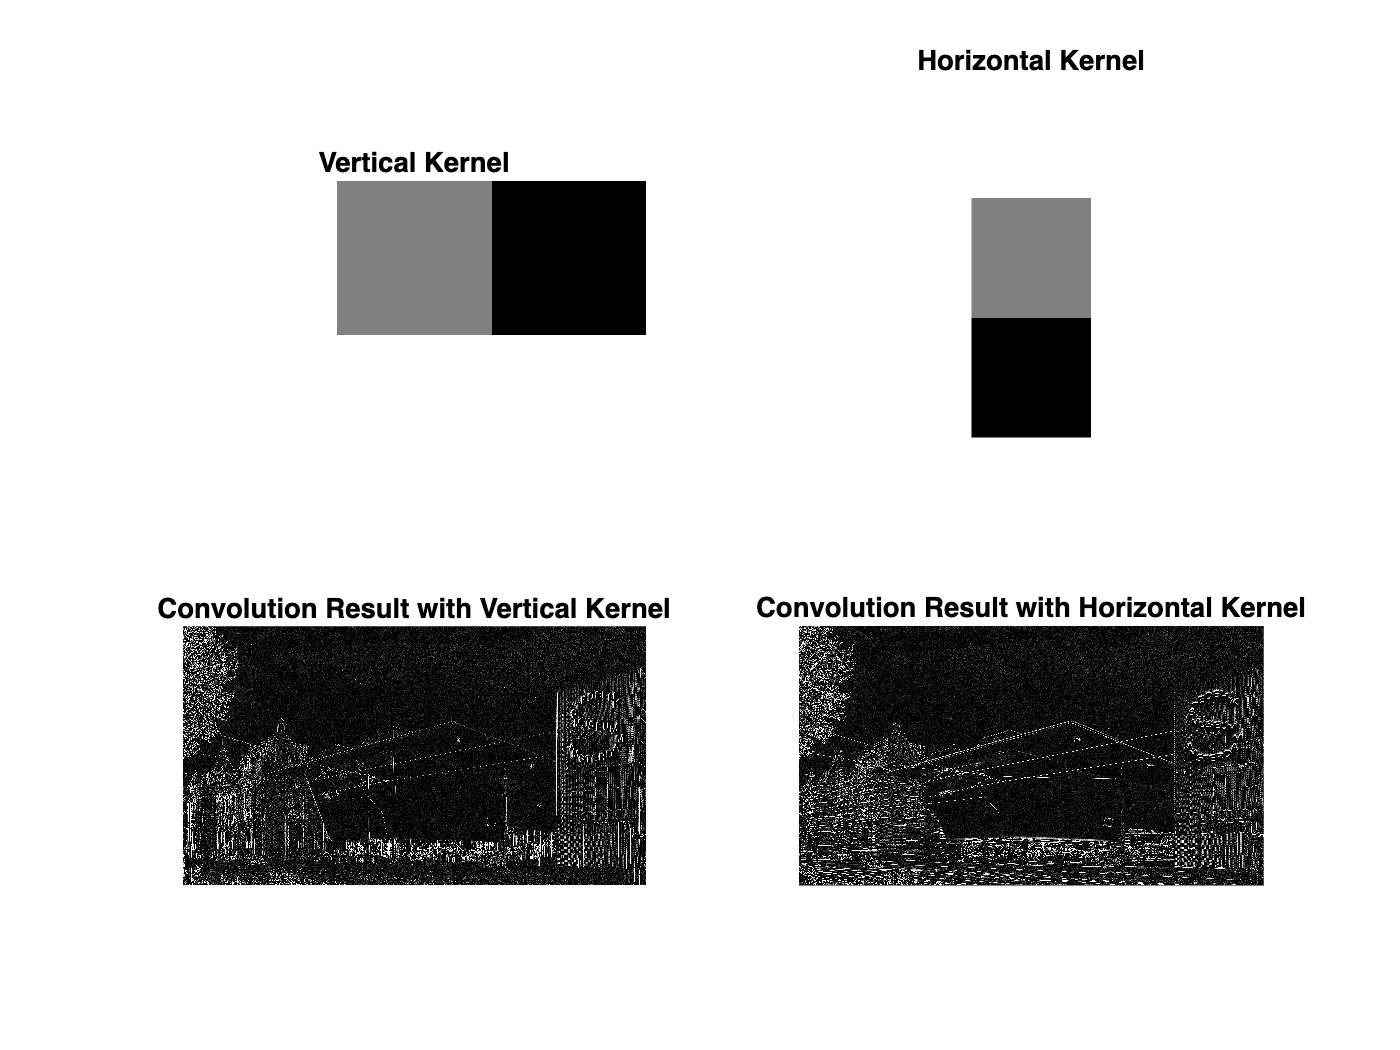


% Convert the image to 2D for convenience (grayscale)
bathtub2d = rgb2gray(bathtub);
bathtub2d = double(bathtub2d);
bathtub2d = (bathtub2d - min(bathtub2d(:))) / (max(bathtub2d(:)) - min(bathtub2d(:)));

% Write here (start)
% Create two feature-detection kernels
VK = [1 0 -1]; % Vertical kernel
HK = [1; 0; -1]; % Horizontal kernel

% Run convolution with the Vertical Kernel
convresVK = conv2(bathtub2d, VK);
% Run convolution with the Horizontal Kernel
convresHK = conv2(bathtub2d, HK);

% Write here (end)

% Display kernels and convolution results
figure;
subplot(2,2,1);
imshow(VK, []);
colormap('gray');
title('Vertical Kernel');

subplot(2,2,2);
imshow(HK, []);
colormap('gray');
title('Horizontal Kernel');

subplot(2,2,3);
imshow(convresVK, [], 'Colormap', gray, 'DisplayRange', [0, max(convresVK(:)) * 0.1]);
axis off;
title('Convolution Result with Vertical Kernel');

subplot(2,2,4);
imshow(convresHK, [], 'Colormap', gray, 'DisplayRange', [0, max(convresHK(:)) * 0.1]);
axis off;
title('Convolution Result with Horizontal Kernel');

### Extra try: Visualization Example

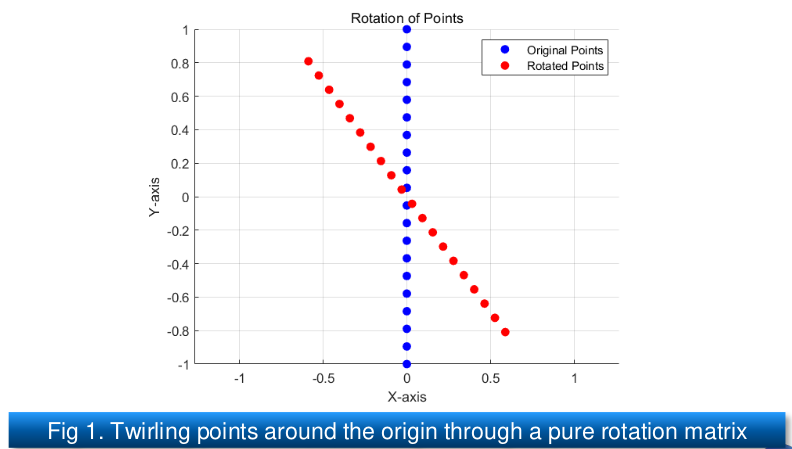

% ■ Consider set of points aligned in a vertical line and effect of multiplying those
%   coordinates by 𝑻.
%      Set 𝜃 = 𝜋/5. How will the results be drawn?
% ■ Before continuing with this section…,
%      Inspect online code that generates this figure.
%      Make sure you understand how Eq 1. is translated into code.
%      Take moment to experiment with different rotation angles.
%      Figure out how to make rotation counterclockwise instead of clockwise as Fig 1..
%         > Answer: Swap minus signs in sine functions

clc; clear; close all;

% y = linspace(-1, 1, 20);
y = -1:0.1:1;
x = zeros(size(y));
plot(x, y, 'b.', MarkerSize=15, DisplayName='Original Points');
hold on;

theta = pi/5

theta = 0.6283

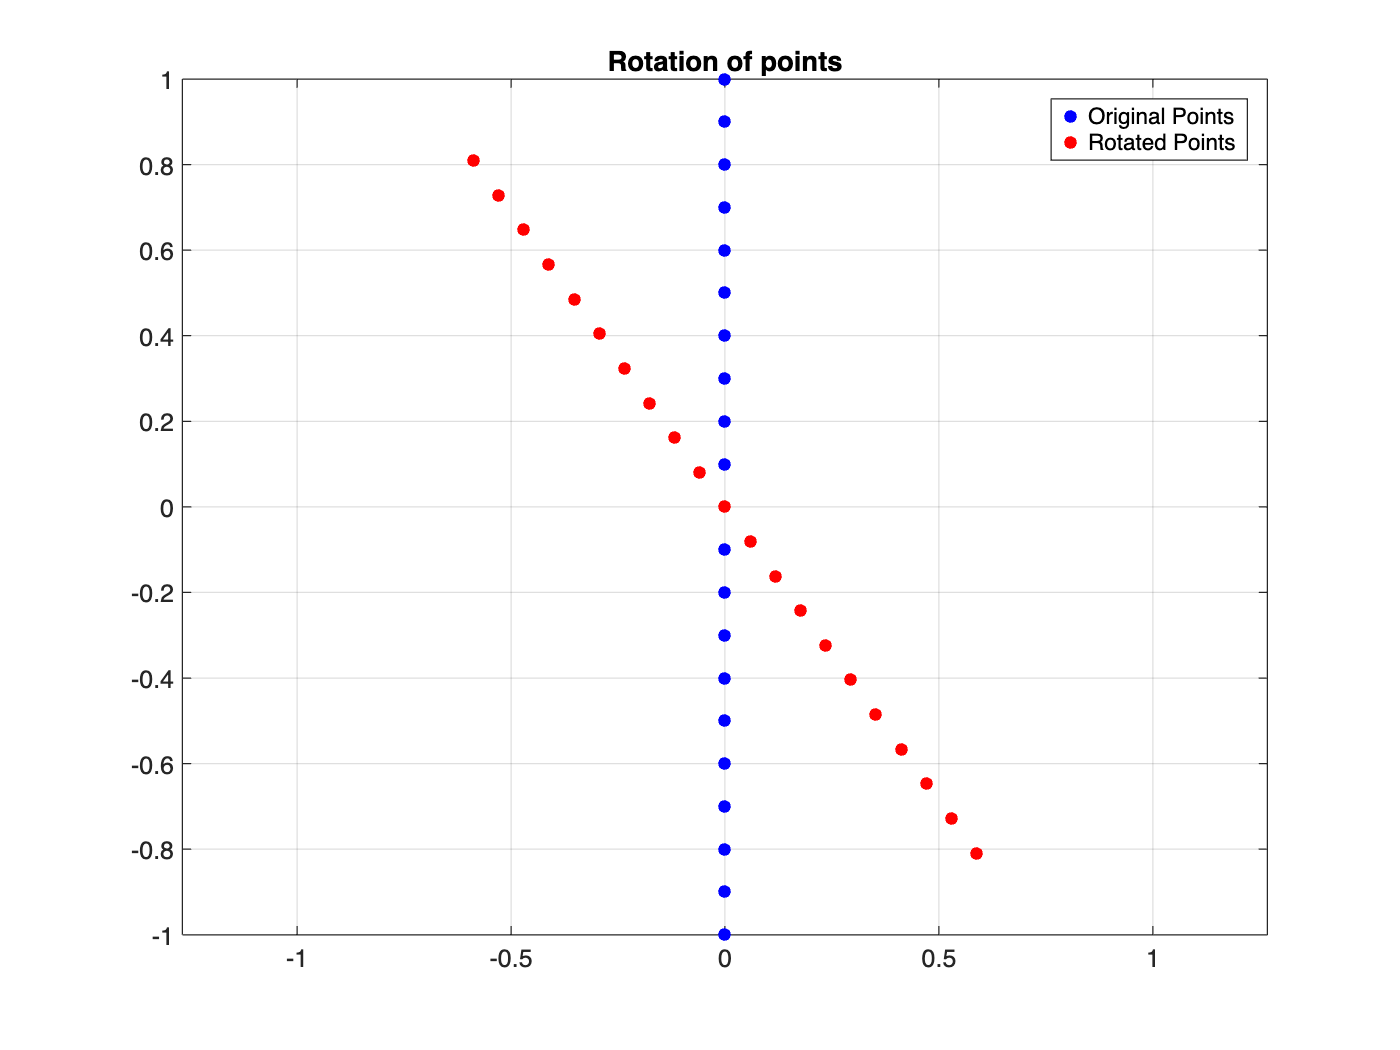

T = [cos(theta) -sin(theta);
    sin(theta), cos(theta)];

points = [x; y];
rotated_points = T * points;

r_x = rotated_points(1, :);  % First row contains x-coordinates
r_y = rotated_points(2, :);  % Second row contains y-coordinates

plot(r_x, r_y, 'r.', 'MarkerSize', 15, DisplayName='Rotated Points');
xlim([-1, 1]);
ylim([-1, 1]);

xlabel = ('X-axis');
ylabel = ('Y-axis');
grid on;
axis equal;

title('Rotation of points');

legend("show");